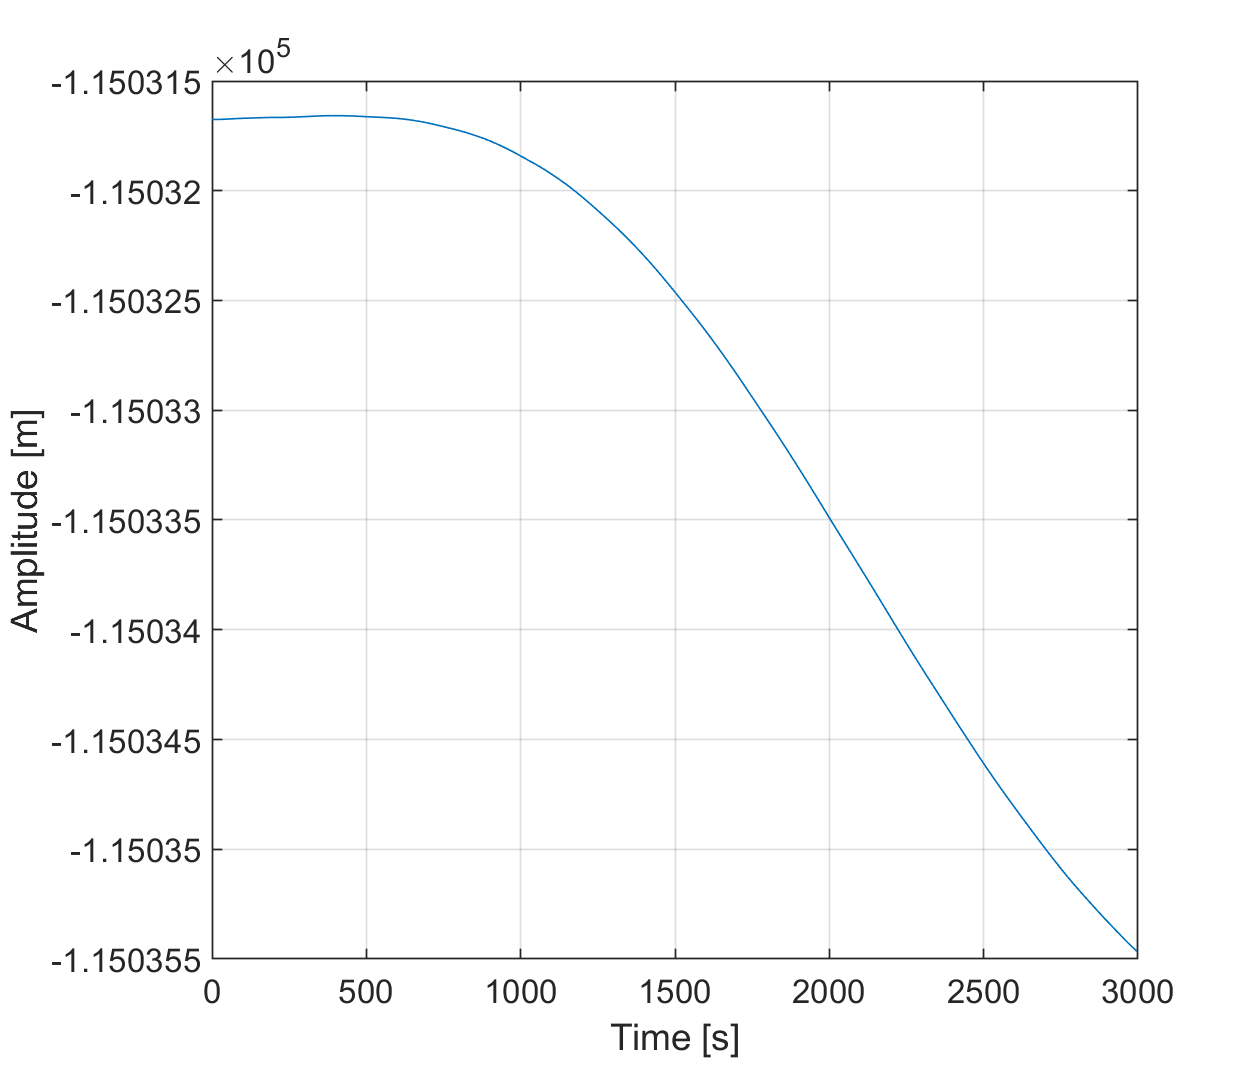

% distance from leading satellite to tracking satellite, computed from the
% simulated trajectory data
% diff_c_d = inertialtrajectory20190101D0411 - inertialtrajectory20190101C0411;
% distance_from_simu = sqrt(diag(diff_c_d * diff_c_d'));

% deprive simulated trajectory and light-time correction from biased range
% eqb = TH0401KBR1B20190101X0820210801000000(:, 1) - TH0401KBR1B20190101X0820210801000000(:, 2) - distance_from_simu;
eqb_5times = repmat(eqb(1: 200), 5, 1);

figure('color', [1 1 1], 'units', 'normalized', 'outerposition', [0 0 1 1]);
plot(1: 5: 3000, eqb(1: 600), 'linewidth', 1); hold on
grid on;
set(gcf, 'Units', 'centimeters', 'Position', [10 10 70 60]);
xlabel('Time [s]', 'fontsize', 20);
ylabel('Amplitude [m]', 'fontsize', 20);
set(gca, 'FontSize', 20, 'linewidth', 1.1)

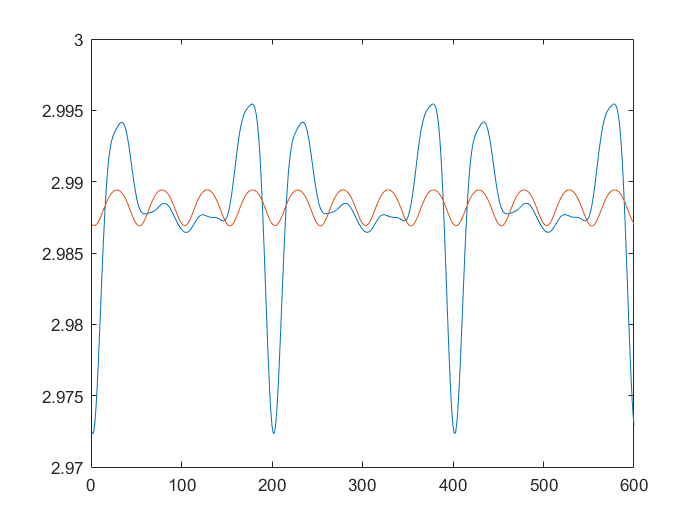

% legend('filtered', 'simulated')

% data wrap
n_times = 5;
eqb_filtered_ntimes = repmat(eqb(1: 200) - mean(eqb(1: 200) - antphasecentrecorr2degree(1: 200)), n_times, 1);
ant_ntimes = repmat(antphasecentrecorr2degree(1: 200), n_times, 1);
eqa_ntimes = repmat(eqa(1: 200, :), n_times, 1);
start_epoch = [201, 401, 601, 801];
eqb_wrap_temp = eqb_filtered_ntimes;
eqb_wrap= eqb_filtered_ntimes;
for i = 1: length(start_epoch)
    temp = interp1(1: start_epoch(i) - 1, eqb_wrap_temp(1: start_epoch(i) - 1), start_epoch(i), 'linear', 'extrap');
    eqb_wrap(start_epoch(i): end) = eqb_wrap(start_epoch(i): end) - eqb_wrap(start_epoch(i)) + temp;
    eqb_wrap_temp = eqb_wrap;
end
figure
plot(filter_pdfree(Num2, eqb_wrap) - mean(filter_pdfree(Num2, eqb_wrap) - match_filter(Num2, ant_ntimes))); hold on;
plot(match_filter(Num2, ant_ntimes));

eqa_1_2_matched = match_filter(Num2, eqa_ntimes);
eqb_1_2_filtered = (filter_pdfree(Num2, eqb_wrap) - mean(filter_pdfree(Num2, eqb_wrap) - match_filter(Num2, ant_ntimes)));
eqb_1_2_filtered_prime = eqa_1_2_matched(:, 3: end) * [-0.0308; 1.5012; 0.0302; 0.0411] - eqb_1_2_filtered;
bbbb = lsqr(eqa_1_2_matched(:, 1: 2), eqb_1_2_filtered_prime, 1e-9, 1e8)

lsqr converged at iteration 2 to a solution with relative residual 0.0028.


bbbb =           1.49365037480768
         0.158530799935753


% lsqr(eqa_1_2_matched, eqb_1_2_filtered, 1e-15, 1e8)
b_error = bbbb(1: 2) + [1.49; 0.02];
b = [1.49; 0.02];
acos(sum((b_error + b) .* b) / norm(b) / norm(b + b_error))

ans =         0.0309266978013626
